x=[0.02 0.02 0.06 0.06 0.11 0.11 0.22 0.22 0.56 0.56 1.10 1.10];
y=[76 47 97 107 123 139 159 152 191 201 207 200];
n= length(y)

n = 12

y1= 1./y'

y1 =     0.0132
    0.0213
    0.0103
    0.0093
    0.0081
    0.0072
    0.0063
    0.0066
    0.0052
    0.0050


x1 = 1./x'

x1 =    50.0000
   50.0000
   16.6667
   16.6667
    9.0909
    9.0909
    4.5455
    4.5455
    1.7857
    1.7857


X=[ones(n,1),x1]

X =     1.0000   50.0000
    1.0000   50.0000
    1.0000   16.6667
    1.0000   16.6667
    1.0000    9.0909
    1.0000    9.0909
    1.0000    4.5455
    1.0000    4.5455
    1.0000    1.7857
    1.0000    1.7857


[b,bint,r,rint,size]= regress(y1,X)

b =     0.0051
    0.0002


bint =     0.0035    0.0067
    0.0002    0.0003


r =    -0.0043
    0.0038
    0.0011
    0.0001
    0.0008
   -0.0002
    0.0001
    0.0003
   -0.0003
   -0.0006


rint =    -0.0050   -0.0037
    0.0021    0.0055
   -0.0032    0.0053
   -0.0042    0.0044
   -0.0035    0.0050
   -0.0045    0.0041
   -0.0042    0.0043
   -0.0039    0.0046
   -0.0045    0.0039
   -0.0048    0.0036


size =     0.8557   59.2975    0.0000    0.0000


disp('b=')

b=


disp(b);

    0.0051
    0.0002



b1 = 1/b(1,1)

b1 = 195.8027

b2 =b(2,1)*b1

b2 = 0.0484

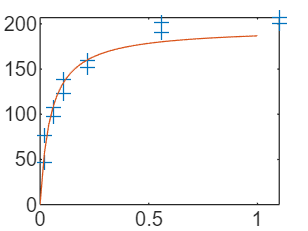

xx= 0:0.02:1;
yy = b1*xx./(b2+xx);
plot(x,y,'+',xx,yy)

x = [0.02 0.02 0.06 0.06 0.11 0.11 0.22 0.22 0.56 0.56 1.10 1.10];
y = [76 47 97 107 123 139 159 152 191 201 207 200];
% 曲线拟合
ft = fittype('a*x^b', 'independent', 'x'); 
[fitresult, gof] = fit(x', y', ft);

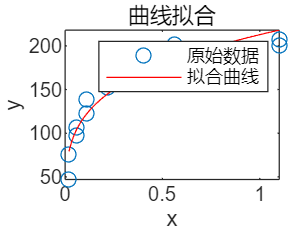

xx = linspace(min(x), max(x), 100);
yy = feval(fitresult, xx);
figure;
plot(x, y, 'o', 'DisplayName', '原始数据');
hold on;
plot(xx, yy, 'r-', 'DisplayName', '拟合曲线');
xlabel('x');
ylabel('y');
title('曲线拟合');
legend show;
hold off;

disp(gof);

           sse: 2.4361e+03
       rsquare: 0.9211
           dfe: 10
    adjrsquare: 0.9132
          rmse: 15.6080

